# Variables

### 1: How to assign?

- You can name the variable whatever you want, as long as it follows some basic conventions

- It cannot start with a number

x = 1

x = 1

### 2: Different Data Types

The '%' symbol indicates a comment. It is not executed when you run your code.

disp('-----------')

-----------


x = 1 % Double

x = 1


y = [1, 2, 3, 4] % Array (horzontile)

y =      1     2     3     4


w = [1;2;3;4] % Array (vertical)

w =      1
     2
     3
     4


z = [1,2,3,4;5,6,7,8] % Array (Matrix)

z =      1     2     3     4
     5     6     7     8



str = "Hello World" % String

str = "Hello World"

ch = 'Hello World' % Character Array

ch = 'Hello World'


logic = true % logical type

logic = logical
   1



TBL = array2table(z) % Table

TBL = 2×4 table
    z1    z2    z3    z4
    __    __    __    __

    1     2     3     4 
    5     6     7     8 


# Operations

The math operations are the same as what you remember from your algebra class.

Notice how for multiplication and division, you need to add a dot before the symbol. This is because the absance of a dot implies a matrix operation (matrix operations are a story for another time).

disp('---------------')

---------------


% Defining Variables:
x = 3

x = 3

y = 2

y = 2


% Operations:
z1 = x + y % Addition

z1 = 5

z2 = x - y

z2 = 1


z3 = x .* y % Multiplication (Notice the '.')

z3 = 6

z4 = x ./ y

z4 = 1.5000


z5 = x .^ y % Exponential

z5 = 9

# Functions

### 1: How Functions Work

Functions take inputs and return outputs. These outputs then assigned to whatever variable you choose.

Take the function ones(): It takes a dimension in and returns an array

disp('--------------')

--------------


x = ones(3) % Notice how it is 3 by 3

x =      1     1     1
     1     1     1
     1     1     1



% Functions can have more than one input.
% They may work differently depending on the number
% of inputs
y = ones(3,2) 

y =      1     1
     1     1
     1     1


z = ones(2,3)

z =      1     1     1
     1     1     1


### 2: Common Functions You Should Know

#### => disp():

We've been using this function the whole time to separate sections!

disp('------------')

------------


The display function will display any datatype you insert into the function.

x = 1; % Use a ';' to surpress outputs!
disp(x)

     1



If you want to write a more complex message, we reccomend that you change everything into a character array and concatinate it together before you display it.

(See the following section on how to transform data types)

msg1 = 'Hello '; 
msg2 = 'World';
disp([msg1 msg2])

Hello World


% ^ putting two char arrays next to each other in
% brackets will concatinate them!

#### => string(), double(), and char()

These will transform whatever data type you insert into them into a different data type

disp('-------------')

-------------


a = 1

a = 1

b = string(1)

b = "1"

c = double(b)

c = 1

The **char()** function is a little bit strange. You can only change strings into chars and chars into strings.

disp('-------------')

-------------


x = "Hello"

x = "Hello"

y = char(x) % works as intended

y = 'Hello'


x = 5

x = 5

z = char(x) % does not work as you may have wanted

z = '□'

#### **=> clear()**

A very simple but useful function. It can be used to remove a variable from the workspace. After you run this function, MATLAB will no longer 'remember' the variables you have cleared.

clear() % Clears ALL current variables

% How to clear only one variable:
x = 1

x = 1

y = x + 1

y = 2

clear("x") % The name of the variable is a string!

#### **=> plot()**

Very powerful in lab. Can be used to plot two arrays of the same dimension

x = [1 2 3 4 5 6]

x =      1     2     3     4     5     6


y = x.^2

y =      1     4     9    16    25    36


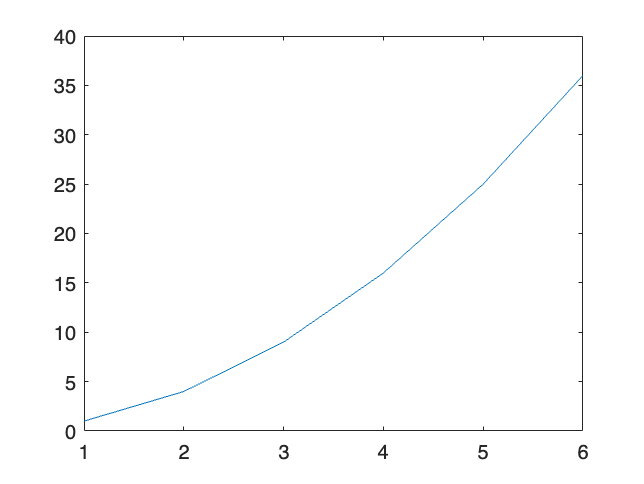


plot(x,y)

You can also change how the data is displayed with the third input to the function. The codes that control the plot can be found online here:

Appearence: [https://www.mathworks.com/help/matlab/creating_plots/specify-line-and-marker-appearance-in-plots.html](https://www.mathworks.com/help/matlab/creating_plots/specify-line-and-marker-appearance-in-plots.html)

Colors: [https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html](https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html)

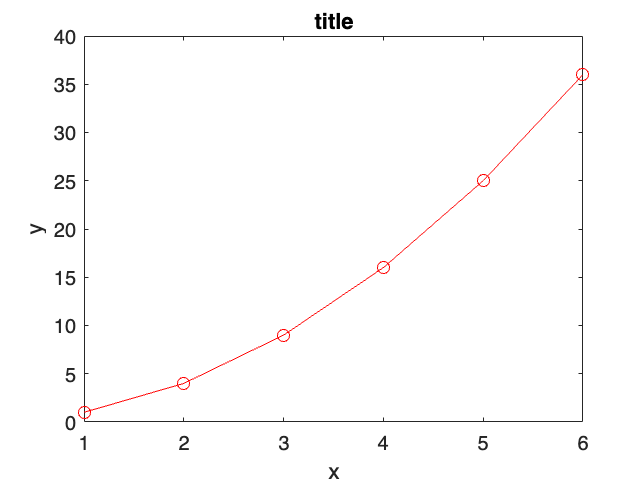

% Example:
plot(x,y,'ro-')

% You can label the graph with the commands:
xlabel("x")
ylabel("y")
title("title")

# Conditionals

These statements can be used to run code based on the value of a logical array. Make sure to use the correct syntax!

#### Example 1: Basic Conditional Structure

x = true 

x = logical
   1


if x % Checks if the statement is true

    disp("Hello") % Body of conditional code

end % You cannot forget the "end" statement

Hello


#### Example 2: Using Logical Operators

The below statement is false if x = 1 and y = 2, so "Hello" will not be displayed!

x = 1

x = 1

y = 2

y = 2


disp("Runs Before Conditional")

Runs Before Conditional


if y <= x % This is false
    disp("Hello")
end
disp("Runs After Conditional")

Runs After Conditional


#### Example 3: Evaluate multiple logical statements at once

You don't need to evaluate the logical statement in the conditional itself. You can assign it to a logical variable type beforehand.

You are also able to use other logical statemetns like "&" for and, "|" for or, and ~ for not.

disp("------------")

------------


x = 1

x = 1

y = 2

y = 2

z = 3

z = 3


condition = x ~= y | y < z

condition = logical
   1



if condition
    disp("Condition is Success!")
end

Condition is Success!


**Example 4: elseif and else**

Sometimes you want your if statement to run another block of code if the first if statement is not satisfied.

disp("--------")

--------


x = 1

x = 1

y = 2

y = 2

z = 3

z = 3


disp("If tree #1")

If tree #1


if x > y
    disp("If Statement is True")
elseif y > x
    disp("elseif statemet is true")
else
    disp("Else condition")
end

elseif statemet is true



disp("If tree #2")

If tree #2


if x > y
    disp("If Statement is True")
elseif y < x
    disp("elseif statemet is true")
else
    disp("Else condition")
end

Else condition


# Loops

Loop statements are the backbone of coding. They allow you to execute the same code over and over again with different parameters

### For Loops:

For loops will iterate through an array over and over again. On each iteration it will take the value in the array

for i = ["Never","Gonna","Give","You","Up"]
    disp(i)
end

Never
Gonna
Give
You
Up



for i = [1,2,3,4,5]
    x = i * 3;
    disp(x)
end

     3

     6

     9

    12

    15



### While Loops:

While loops will continue looping until the condition is false. You can thing of it like a looping if statement.

x = 0

x = 0

y = 6

y = 6


while x < y
    x = x + 1;
    disp(x)
end

     1

     2

     3

     4

     5

     6



### Loop Example: Solving Differential Equations:

You can use for loops to solve differential equations by brute force. Here we used it to solve x = -x''

The following code was generated using Chat-GPT 3.5:

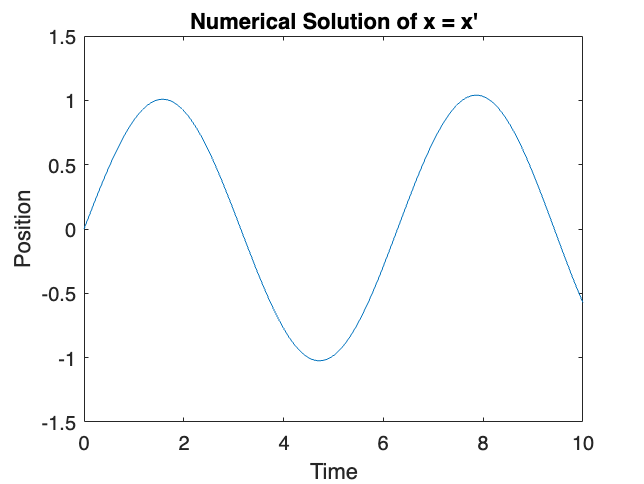

% Define the time span and time step
tspan = [0, 10];  % Time span from 0 to 10
dt = 0.01;       % Time step

% Create an array to store the time values
t = tspan(1):dt:tspan(2);

% Initialize arrays to store the values of x and x'
x = zeros(size(t));
x_prime = zeros(size(t));

% Initial conditions
x(1) = 0;      % Initial position
x_prime(1) = 1;  % Initial velocity

% Numerical integration using a for loop
for i = 1:length(t)-1
    x_double_prime = -1 * x(i);  % Second derivative (x'')
    
    % Update x' (velocity) and x (position) using Forward Euler method
    x_prime(i+1) = x_prime(i) + x_double_prime * dt;
    x(i+1) = x(i) + x_prime(i) * dt;
end

% Plot the solution
plot(t, x);
xlabel('Time');
ylabel('Position');
title('Numerical Solution of x = x''');